# 在一个 figure 里绘制多幅伪彩图，分别用不同的颜色显示

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

思路：绘图时设置的 colormap 默认都是针对整个 figure 的，如需用不同的颜色需要单独再设置 colormap 属性。

也有一个开源函数 freezeColors 可用，链接如下：

[https://ww2.mathworks.cn/matlabcentral/fileexchange/7943-freezecolors-unfreezecolors](https://ww2.mathworks.cn/matlabcentral/fileexchange/7943-freezecolors-unfreezecolors)

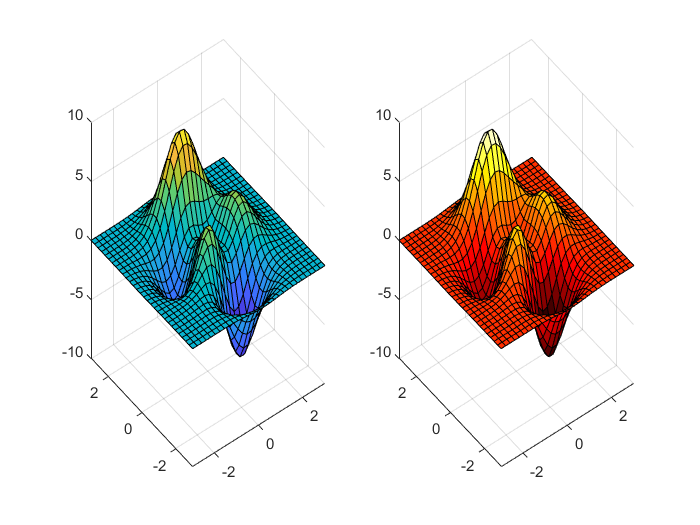

clear;clc;
[x, y, z] = peaks(30);
figure;
plot1 = subplot(1,2,1);
surf(x, y, z);
% 获取第一幅图的 colormap，默认为 parula
cMap = colormap;
plot2 = subplot(1,2,2);
surf(x, y, z);
% 下面设置的是第二幅图的颜色，默认是整个 figure 的
colormap(hot);
% 设置第一幅图颜色显示为 parula
set(plot1, 'Colormap', cMap);

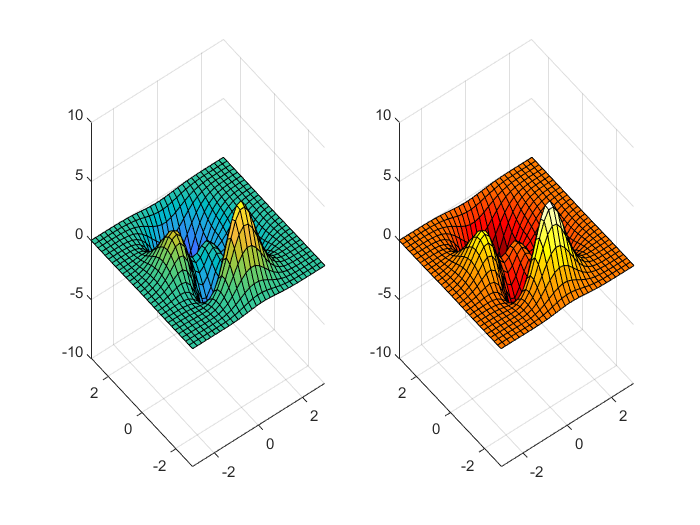

% 用 freezeColors 方法
figure;
subplot(1,2,1);
surf(x, y, -z);
freezeColors;
subplot(1,2,2);
surf(x, y, -z);
colormap(hot);